# Covnerge Analysis of SAFE implementation

We will start the convergence analysis by examining the convergence rate of the original IWFM method.

The test 1 example simulates the flow in 12 time steps, where each time step is solved iteratively. In the follwoing we will examine the number of Newton Raphson  iterations required eacn time step. We will also examine how this rate is affected by the various parameters

## IWFM 4.1    

### Convergence wrt to $K_{\textrm{cl}}$

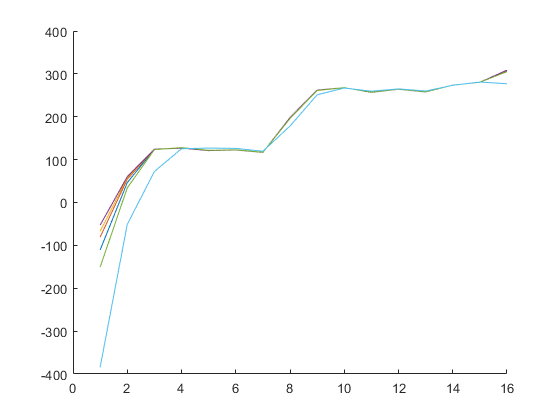

figure()
clf
hold on
for ii = 1:length(IWFM41)
    plot(IWFM41(ii,1).SWGW.GwIn(2:end,12));
end
grid on

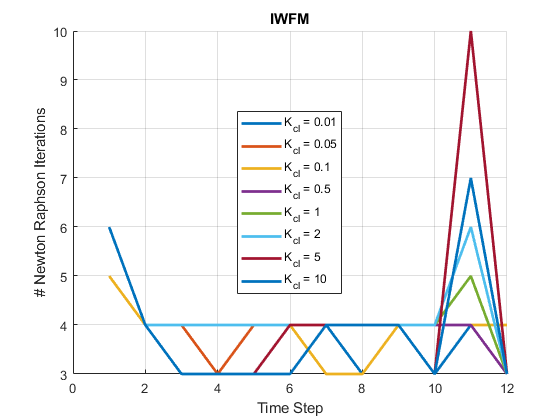

figure()
clf
hold on
for ii = 1:length(IWFM41)
    plot([IWFM41(ii,1).CONV.Niter]','DisplayName',IWFM41(ii,1).Desc, 'LineWidth',2);
end
grid on
legend('Location','best')
xlabel('Time Step')
ylabel('# Newton Raphson Iterations')
title('IWFM')

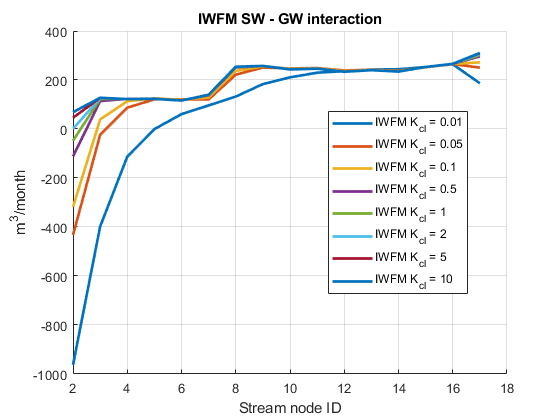

figure()
clf
hold on
for ii = 1:length(IWFM41)
    plot(2:17, IWFM41(ii,1).SWGW.GwIn(2:end,8),'DisplayName',['IWFM ' IWFM41(ii,1).Desc], 'LineWidth',2)
end
legend('Location',"best")
grid on
xlabel('Stream node ID')
ylabel('m^3/month')
title ('IWFM SW - GW interaction')

## SAFE

## Convergence wrt to $K_{\mathrm{cl}}$

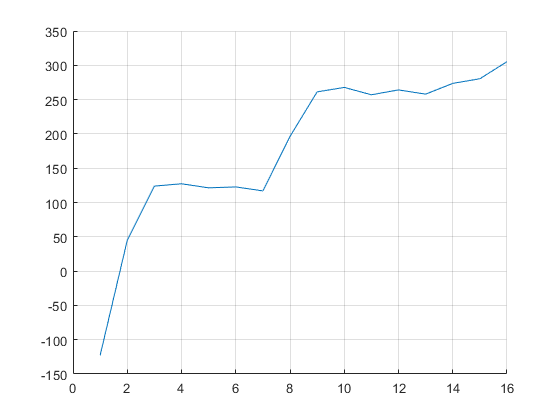

figure()
clf
hold on
for ii = 1:length(SAFE)
    plot(SAFE(ii,1).SWGW.GwIn(2:end,12));
end
grid on

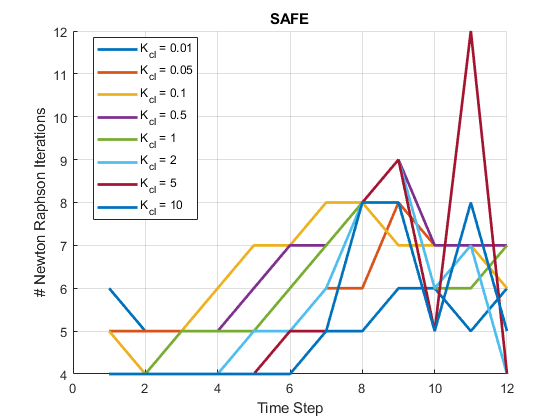

figure()
clf
hold on
for ii = 1:length(IWFM41)
    plot([SAFE(ii,1).CONV.Niter]','DisplayName',IWFM41(ii,1).Desc, 'LineWidth',2);
end
grid on
legend('Location','best')
xlabel('Time Step')
ylabel('# Newton Raphson Iterations')
title('SAFE')

## Compare IWFM to SAFE

### Converge iterations

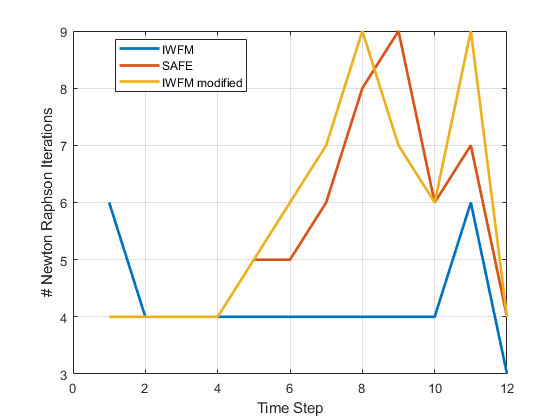

figure()
clf
plot([IWFM41(1,1).CONV.Niter]','DisplayName','IWFM', 'LineWidth',2)
hold on
plot([SAFE(1,1).CONV.Niter]','DisplayName','SAFE', 'LineWidth',2)
plot([IWFM41mod(1,1).CONV.Niter]','DisplayName','IWFM modified', 'LineWidth',2)
grid on
xlabel('Time Step')
ylabel('# Newton Raphson Iterations')
legend('Location',"best")

### SW-GW interaction

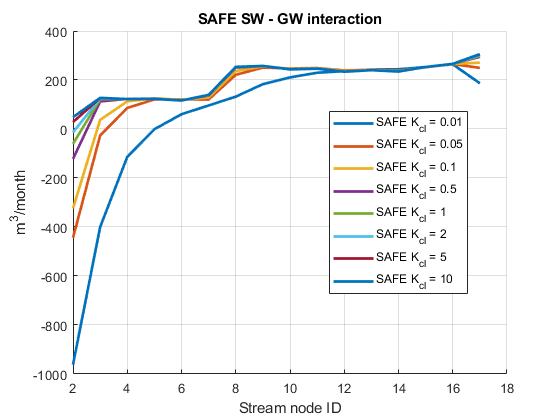

figure()
clf
hold on
for ii = 1:length(SAFE)
    plot(2:17, SAFE(ii,1).SWGW.GwIn(2:end,8),'DisplayName',['SAFE ' SAFE(ii,1).Desc], 'LineWidth',2)
end
legend('Location',"best")
grid on
xlabel('Stream node ID')
ylabel('m^3/month')
title ('SAFE SW - GW interaction')

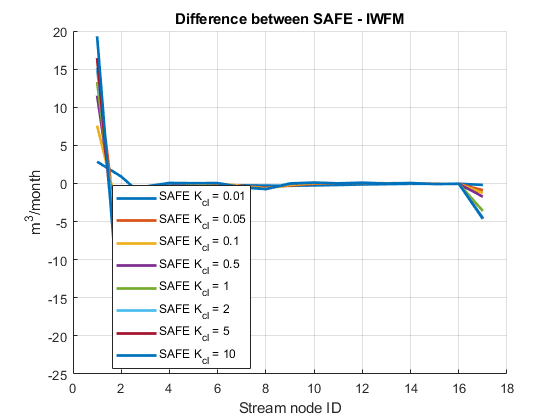

figure()
clf
hold on
for ii = 1:length(SAFE)
    plot(1:17, SAFE(ii,1).SWGW.GwIn(1:end,8) - IWFM41(ii,1).SWGW.GwIn(1:end,8),'DisplayName',['SAFE ' SAFE(ii,1).Desc], 'LineWidth',2)
end
legend('Location',"best")
grid on
xlabel('Stream node ID')
ylabel('m^3/month')
title ('Difference between SAFE - IWFM')